# Decentralized OPF

clearVars = true;
if strcmp(getenv('USERNAME'), 'aryan')
    % For user 'aryan', change the current directory to the specified path
    cd('C:\Users\aryan\Documents\documents_general\dablab_files\DOPF_1Phase_dablab\')
    addpath('functions\')
end
addDirectories;

clearVariables(clearVars);

start = tic;
    
systemName = 'ieee123'

systemName = 'ieee123'

numAreas = 4

numAreas = 4

systemDataFolder = strcat("rawData/", systemName, "/numAreas_", num2str(numAreas), "/");

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
N = max(actualBusNums);

loss_min = true;   % CVR  = 0, Loss minimization = 1;
itrMax = 20; %Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
eps = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = true;
displayActualBusNumbersInGraphs = true;
saveNetworkGraphPlots = true;
saveSimulationResults = true;
displaySimulationResultPlots = true;
saveSimulationResultPlots = true;

CVR = [0; 0]; %as opposed to [0.6; 3.0]

load_mult = 1;
gen_mult = 1;

verbose = false;
V_min = 0.95;
V_max = 1.05;

kVA_B = 1000;                                        % base kVA
kV_B = 4.16/sqrt(3);  

% [CBMatrix, CBTable] = extractConnectionData(systemDataFolder, 'verbose', true);
[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parentArea = CBTable.parentArea(relationshipNum);
    isLeaf(parentArea, 1) = 0;
    childArea = CBTable.childArea(relationshipNum);
    isRoot(childArea, 1) = 0;
    numChildAreas(parentArea) = numChildAreas(parentArea) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);
S_allRelationships = CBTable.S_childArea;

S_parent = zeros(numAreas, 1);
S_child = zeros(N, numAreas);
v2_parent = 1.03^2*ones(numAreas, 1);
v2 = zeros(N, numAreas);
decisionVars = zeros(N, numAreas);
N_Areas = zeros(numAreas, 1);

#### Start with the algorithm

keepRunningIterations = 1;
itr = 0;
time_dist = zeros(itrMax, numAreas);
microIterationLosses = zeros(itrMax, numAreas);
R_max = zeros(itrMax, 1);

while keepRunningIterations

Run one macro-iteration, i.e. one OPF on each area

Plotting for Area 1:
This area has only the substation as its 'parent area'.
This area has 2 child areas, which include the Areas: Area 2 and Areas 3.


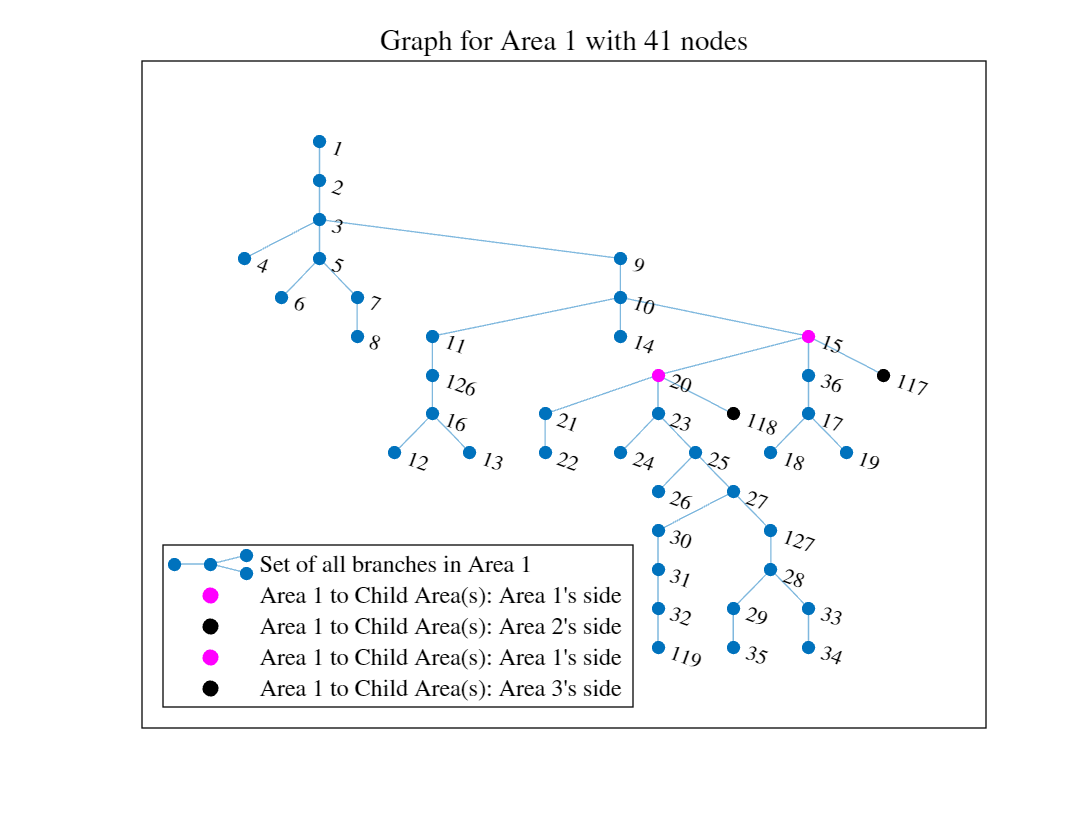

Plotting for Area 2:
This area's parent is Area 1.
This area has 1 child area: Area 4.


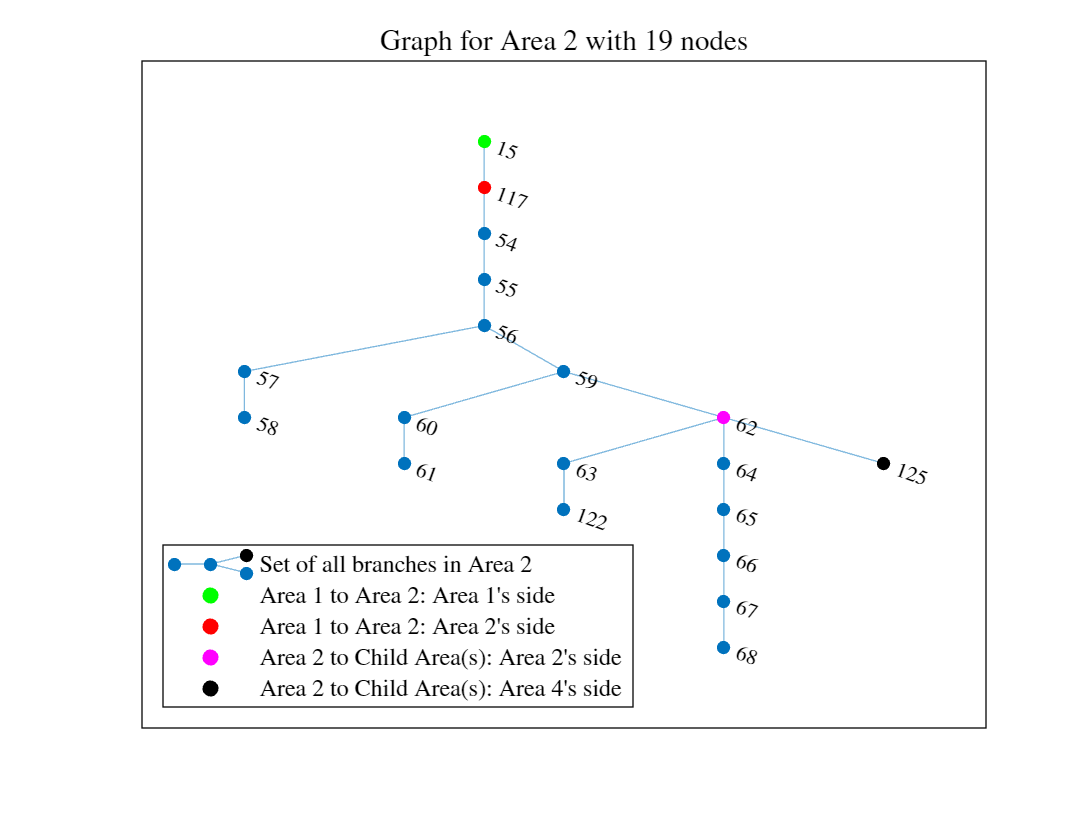

Plotting for Area 3:
This area's parent is Area 1.
This area has no child areas.


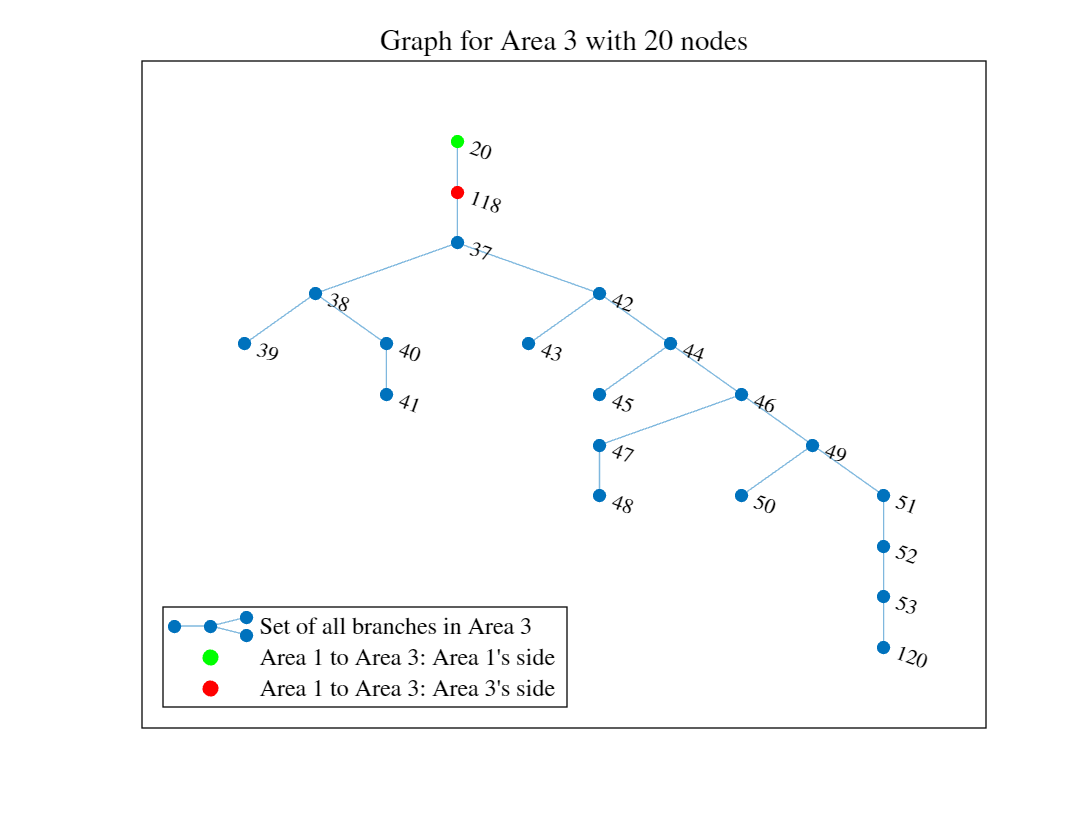

Plotting for Area 4:
This area's parent is Area 2.
This area has no child areas.


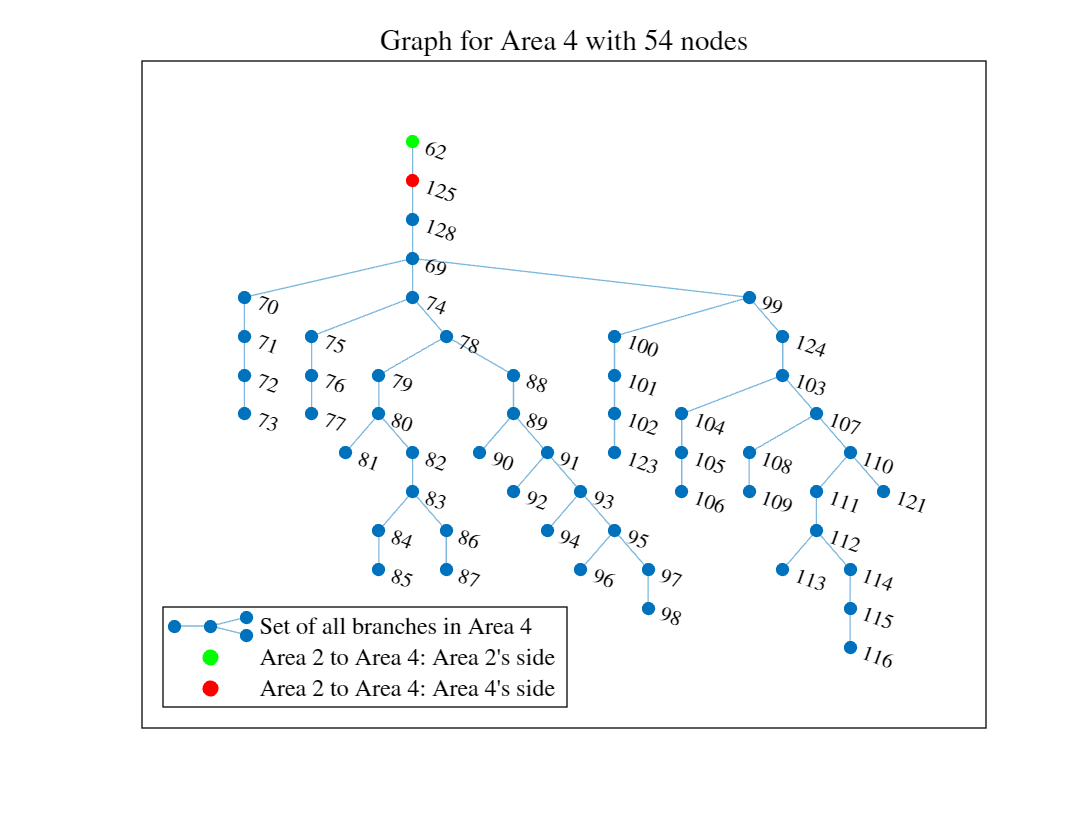

Still yet to converge after 0 iterations, continuing.
Still yet to converge after 1 iterations, continuing.
Still yet to converge after 2 iterations, continuing.
Still yet to converge after 3 iterations, continuing.
Still yet to converge after 4 iterations, continuing.


Converged in 5 iterations!


    for Area = 1 : numAreas

        v2_parent_Area = v2_parent(Area);
        S_childAreas = S_allRelationships(CBTable.parentArea == Area);

        isLeaf_Area = isLeaf(Area);
        isRoot_Area = isRoot(Area);
        numChildAreas_Area = numChildAreas(Area);

        [v2_Area, S_parent_Area, S_child_Area, ...
            microIterationLosses, decisionVars_Area, ...
            itr, time_dist, R, T_Area, N_Area, busDataTable_Area, branchDataTable_Area] = ...
            NL_OPF_dist(v2_parent_Area, ...
            S_childAreas, ...
            Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, N, CVR, ...
            kV_B, kVA_B, load_mult, gen_mult, ...
            V_max, V_min, systemName, numAreas, ...
            systemDataFolder, ...
            microIterationLosses, time_dist, itr, ...
            CBTable, displayTables, displayNetworkGraphs, ...
            displayActualBusNumbersInGraphs, saveNetworkGraphPlots, verbose);
        
        N_Areas(Area) = N_Area;
        S_parent(Area) = S_parent_Area;
       
        decisionVars(1:N_Area, Area) = decisionVars_Area;
        v2(1:N_Area, Area) = v2_Area;   % Storing all the square of the node voltages
        S_child(1:N_Area, Area) = S_child_Area;   % Storing all the S flow of the Area
        
    end
    
    % Residual Matrix:

    for relationshipNum = 1 : numRelationships

        parentArea = CBTable.parentArea(relationshipNum);
        childArea = CBTable.childArea(relationshipNum);
        parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
        parentAreaOutflowingPower = S_child(parentAreaConnectingBus - 1, parentArea);
        childAreaInflowingPower = S_parent(childArea);

        powerflowDifference = parentAreaOutflowingPower - childAreaInflowingPower;

        parentAreaConnectingBusVoltage = v2(parentAreaConnectingBus, parentArea);
        childAreaConnectingBusVoltage = v2_parent(childArea);

        voltageDifference = parentAreaConnectingBusVoltage - childAreaConnectingBusVoltage;

        R = [powerflowDifference; voltageDifference];
        
        if max(abs(R)) > R_max(itr+1)
            R_max(itr+1) = max(abs(R));
        end

    end
    
    if itr > itrMax
        fprintf("Didn't converge even in %d iterations, terminating.\n", itrMax);
        keepRunningIterations = 0;

    elseif R_max(itr+1) < eps
        fprintf("Converged in %d iterations!\n", itr);
        keepRunningIterations = 0;
        R_max = R_max(1:itr);

    else % Checking if any boundary converged or no t.
        fprintf("Still yet to converge after %d iterations, continuing.\n", itr)
        a(1) = 0.25;
        a(2) = 0.05;
        %Communication-
        
        for relationshipNum = 1:numRelationships
            V_iter(itr+1, CBTable.conBus_parentAreaTo(relationshipNum),CBTable.parentArea(relationshipNum)) = v2(CBTable.conBus_parentAreaTo(relationshipNum),CBTable.parentArea(relationshipNum)) ;
            Se_iter(itr+1,CBTable.childArea(relationshipNum)) = S_parent(CBTable.childArea(relationshipNum));
            
            if itr > 2
                v2_parent(CBTable.childArea(relationshipNum)) = a(2)*V_iter(itr-1,CBTable.conBus_parentAreaTo(relationshipNum),CBTable.parentArea(relationshipNum))+...
                    a(1)*V_iter(itr,CBTable.conBus_parentAreaTo(relationshipNum),CBTable.parentArea(relationshipNum))+...
                    (1-sum(a))*v2(CBTable.conBus_parentAreaTo(relationshipNum),CBTable.parentArea(relationshipNum)) ;
                
                S_allRelationships(relationshipNum, 1) = a(2)*Se_iter(itr-1,CBTable.childArea(relationshipNum))+...
                    a(1)*Se_iter(itr,CBTable.childArea(relationshipNum))+...
                    (1-sum(a))*S_parent(CBTable.childArea(relationshipNum));
            else
                v2_parent(CBTable.childArea(relationshipNum)) = v2(CBTable.conBus_parentAreaTo(relationshipNum),CBTable.parentArea(relationshipNum));
                S_allRelationships(relationshipNum, 1) = S_parent(CBTable.childArea(relationshipNum));
            end
        end

        itr = itr + 1;
    end

    
end

#### Post Processing

V_node_sq = zeros(N, 1);
V_node_sq(1) = v2_parent(1);
Dec_Var_overall = 0;
for Area = 1:numAreas
    busesCounted = 1;
    N_Area = N_Areas(Area);
    v_area1 = v2(2:min(CBMatrix((find(Area==CBTable.parentArea)),3))-1,Area);
    DV_area1 = decisionVars(2:min(CBMatrix((find(Area==CBTable.parentArea)),3))-1,Area);
    
    if isLeaf(Area)
        v_area1 = v2(2:N_Area, Area);
        DV_area1 = decisionVars(2:N_Area, Area);         
    end

    fprintf("Number of child nodes in Area %d = %d.\n", Area, length(v_area1));
    
    V_node_sq(busesCounted+1, busesCounted+length(v_area1)) = v_area1;
    busesCounted = busesCounted + N_Area;
    % V_node_sq = [V_node_sq;v_area1];
    Dec_Var_overall = [Dec_Var_overall;DV_area1 ];
    
end

Number of child nodes in Area 1 = 38.


Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 38-by-1.


V_node_sq_1 = zeros(N, 1);
Dec_Var_overall_1 = zeros(N, 1);

for j = 1:N
    V_node_sq_1( actualBusNums(j) ) = V_node_sq(j);
    Dec_Var_overall_1(actualBusNums(j),1) = Dec_Var_overall(j);
end
%
v1 = transpose(sqrt(V_node_sq_1));
v1_actual = v1(actualBusNums);
decisionVars = Dec_Var_overall_1';

microIterationLosses = microIterationLosses(1:itr, :);
time_dist = time_dist(1:itr, :);

macroIterationLossesTotal = 1000*sum(microIterationLosses, 2); %sum over each row
%representing each iteration
dist_timeTotal = sum(time_dist, 2);

if displaySimulationResultPlots
    displayAndSaveSimulationResultPlots(itr, macroIterationLossesTotal, dist_timeTotal, R_max, v1_actual, saveSimulationResultPlots, Area, systemName, numAreas);
end

lineLoss_kW = macroIterationLossesTotal(itr);
substationPower_kW = real(S_child(1))*1000;
timeToSolveOPFs_s = max(sum(time_dist));

disp('------------------------------------------------------------')
disp(['Line Loss: ', num2str(lineLoss_kW),' kW'])                       
disp(['Substation Power: ', num2str(substationPower_kW),' kW'])
disp(['Number of Iterations: ', num2str(itr)])
disp(['Time to Solve: ', num2str(timeToSolveOPFs_s), 's'])
disp('------------------------------------------------------------')

programRunTime = toc(start)

if saveSimulationResults
    saveResults(systemName, numAreas, lineLoss_kW, substationPower_kW, timeToSolveOPFs_s, itr, programRunTime);
end